Just setting up data points

theta_full = pi/180:pi/180:2*pi;
mu = 54*pi/180;
sigma = 10*pi/180;
data_fab = normpdf(theta_full,mu,sigma);

rawdata1 = data_fab + circshift(data_fab', 180)';
rawdata2 = circshift(rawdata1', 30)';
rawdata3 = circshift(rawdata1', 45)';
rawdata4 = circshift(rawdata1', 50)';

data_point1 = data_point;
data_point2 = data_point;
data_point3 = data_point;
data_point4 = data_point;

data_point1.intensity_data = rawdata1;
data_point2.intensity_data = rawdata2;
data_point3.intensity_data = rawdata3;
data_point4.intensity_data = rawdata4;

data_point1 = data_point1.Normalize;
data_point1 = data_point1.GenerateFourier(14);
data_point2 = data_point2.Normalize;
data_point2 = data_point2.GenerateFourier(14);
data_point3 = data_point3.Normalize;
data_point3 = data_point3.GenerateFourier(14);
data_point4 = data_point4.Normalize;
data_point4 = data_point4.GenerateFourier(14);


data_point1.x = 0;
data_point1.y = 0;

data_point2.x = 1;
data_point2.y = 0;

data_point3.x = 0;
data_point3.y = 1;

data_point4.x = 1;
data_point4.y = 1;

Where to interpolate at

x_prime = 0.25;
y_prime = 0.25;

**Method one: Using bilinear interpolation**


data_pointI = data_point; % data point - registered data point
data_pointI.x = x_prime;
data_pointI.y = y_prime;
data_pointI.an = [];
data_pointI.bn = [];
 
for i=1:length(data_point1.an)
    a = u(data_pointI.x,data_pointI.y, data_point1.an(i),data_point2.an(i),data_point3.an(i),data_point4.an(i));
    b = u(data_pointI.x,data_pointI.y, data_point1.bn(i),data_point2.bn(i),data_point3.bn(i),data_point4.bn(i));
    
    data_pointI.an = [data_pointI.an a];
    data_pointI.bn = [data_pointI.bn b];
end

fit1 = evalFourierRad(data_point1.an, data_point1.bn, 1, theta_full);
fit2 = evalFourierRad(data_point2.an, data_point2.bn, 1, theta_full);
fit3 = evalFourierRad(data_point3.an, data_point3.bn, 1, theta_full);
fit4 = evalFourierRad(data_point4.an, data_point4.bn, 1, theta_full);
fitI = evalFourierRad(data_pointI.an, data_pointI.bn, 1, theta_full);

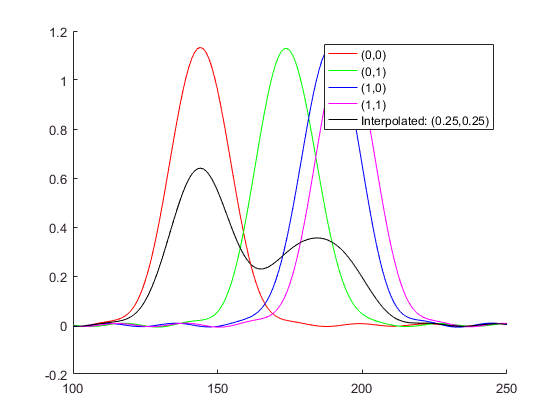

figure
hold on 
plot(100:250, fit1(100:250), 'r');
plot(100:250, fit2(100:250), 'g');
plot(100:250, fit3(100:250), 'b');
plot(100:250, fit4(100:250), 'm');
plot(100:250, fitI(100:250), 'k');
legend('(0,0)','(0,1)','(1,0)','(1,1)',sprintf('Interpolated: (%.2f,%.2f)',x_prime,y_prime));
hold off

**Method 2: Blending of Data**

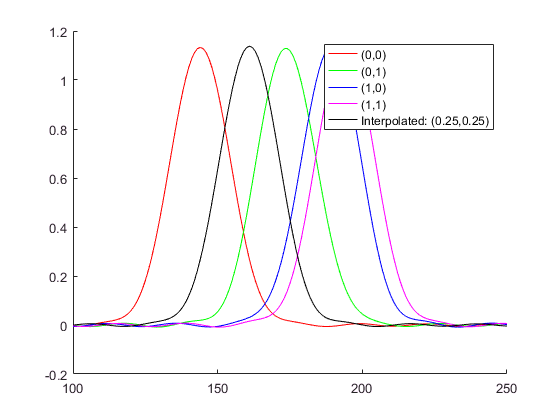


data_point1 = data_point1.ComputeStats;
data_point2 = data_point2.ComputeStats;
data_point3 = data_point3.ComputeStats;
data_point4 = data_point4.ComputeStats;

data_point3.mean_odd = data_point3.mean_odd + pi;
data_point3.mean_odf = data_point3.mean_odf + pi;
data_point4.mean_odd = data_point4.mean_odd + pi;
data_point4.mean_odf = data_point4.mean_odf + pi;

%Bilinear Interpolation of PrefD
prefD_I = u(data_pointI.x,data_pointI.y, data_point1.mean_odf,data_point2.mean_odf,data_point3.mean_odf,data_point4.mean_odf);
    
%Rotate Data to this PrefD
newData1 = data_point;
newData2 = data_point;
newData3 = data_point;
newData4 = data_point;

%I want to rotate Tensor coordinates, not shift the actual data
deg1 = (prefD_I - data_point1.mean_odd)*(180/pi);
newData1.intensity_data = circshift(data_point1.intensity_data', round(deg1))';
deg2 = (prefD_I - data_point2.mean_odd)*(180/pi);
newData2.intensity_data = circshift(data_point2.intensity_data', round(deg2))';
deg3 = (prefD_I - data_point3.mean_odd)*(180/pi);
newData3.intensity_data = circshift(data_point3.intensity_data', round(deg3))';
deg4 = (prefD_I - data_point4.mean_odd)*(180/pi);
newData4.intensity_data = circshift(data_point4.intensity_data', [round(deg4),0])';

newData1 = newData1.Normalize;
newData1 = newData1.GenerateFourier(14);
newData2 = newData2.Normalize;
newData2 = newData2.GenerateFourier(14);
newData3 = newData3.Normalize;
newData3 = newData3.GenerateFourier(14);
newData4 = newData4.Normalize;
newData4 = newData4.GenerateFourier(14);

%Bilinear Interpolation of Rotated Fourier Coefficients

data_pointI2 = data_point; % data point - registered data point
data_pointI2.x = x_prime;
data_pointI2.y = y_prime;
data_pointI2.an = [];
data_pointI2.bn = [];
 
for i=1:length(newData1.an)
    a = u(data_pointI2.x,data_pointI2.y, newData1.an(i),newData2.an(i),newData3.an(i),newData4.an(i));
    b = u(data_pointI2.x,data_pointI2.y, newData1.bn(i),newData2.bn(i),newData3.bn(i),newData4.bn(i));
    
    data_pointI2.an = [data_pointI2.an a];
    data_pointI2.bn = [data_pointI2.bn b];
end

%data_pointI2.intensity_data = evalFourierRad(data_pointI2.an, data_pointI2.bn, 1, theta_full);
%data_pointI2 = data_pointI2.Normalize;
%data_pointI2 = data_pointI2.GenerateFourier(14);

%Plot that shit
fitI2 = evalFourierRad(data_pointI2.an, data_pointI2.bn, 1, theta_full);
figure
hold on 
plot(100:250, fit1(100:250), 'r');
plot(100:250, fit2(100:250), 'g');
plot(100:250, fit3(100:250), 'b');
plot(100:250, fit4(100:250), 'm');
plot(100:250, fitI2(100:250), 'k');
legend('(0,0)','(0,1)','(1,0)','(1,1)',sprintf('Interpolated: (%.2f,%.2f)',x_prime,y_prime));
hold off

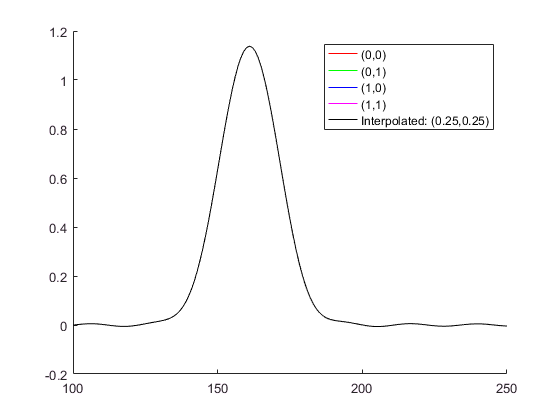


%Alt plot
nd_fit1 = evalFourierRad(newData1.an, newData1.bn, 1, theta_full);
nd_fit2 = evalFourierRad(newData2.an, newData2.bn, 1, theta_full);
nd_fit3 = evalFourierRad(newData3.an, newData3.bn, 1, theta_full);
nd_fit4 = evalFourierRad(newData4.an, newData4.bn, 1, theta_full);

figure
hold on 
plot(100:250, nd_fit1(100:250), 'r');
plot(100:250, nd_fit2(100:250), 'g');
plot(100:250, nd_fit3(100:250), 'b');
plot(100:250, nd_fit4(100:250), 'm');
plot(100:250, fitI2(100:250), 'k');
legend('(0,0)','(0,1)','(1,0)','(1,1)',sprintf('Interpolated: (%.2f,%.2f)',x_prime,y_prime));
hold off


%%


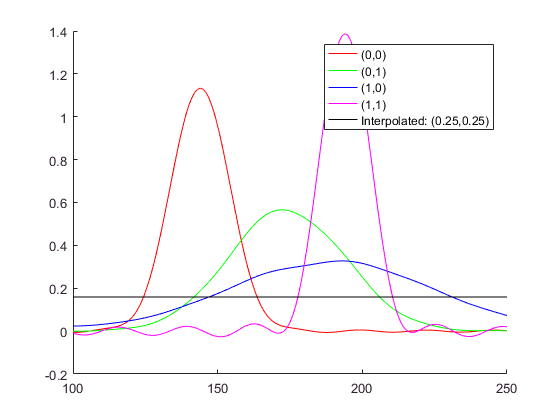

%Varying Distributions

%New data point
theta_full = pi/180:pi/180:2*pi;
mu1 = 54*pi/180;
sigma1 = 10*pi/180;
data_fab1 = normpdf(theta_full,mu1,sigma1);
mu2 = 84*pi/180;
sigma2 = 20*pi/180;
data_fab2 = normpdf(theta_full,mu2,sigma2);
mu3 = 99*pi/180;
sigma3 = 35*pi/180;
data_fab3 = normpdf(theta_full,mu3,sigma3);
mu4 = 104*pi/180;
sigma4 = 8*pi/180;
data_fab4 = normpdf(theta_full,mu4,sigma4);

rawdata1 = data_fab1 + circshift(data_fab1', 180)';
rawdata2 = data_fab2 + circshift(data_fab2', 180)';
rawdata3 = data_fab3 + circshift(data_fab3', 180)';
rawdata4 = data_fab4 + circshift(data_fab4', 180)';

data_point1 = data_point;
data_point2 = data_point;
data_point3 = data_point;
data_point4 = data_point;

data_point1.intensity_data = rawdata1;
data_point2.intensity_data = rawdata2;
data_point3.intensity_data = rawdata3;
data_point4.intensity_data = rawdata4;

data_point1 = data_point1.Normalize;
data_point1 = data_point1.GenerateFourier(14);
data_point2 = data_point2.Normalize;
data_point2 = data_point2.GenerateFourier(14);
data_point3 = data_point3.Normalize;
data_point3 = data_point3.GenerateFourier(14);
data_point4 = data_point4.Normalize;
data_point4 = data_point4.GenerateFourier(14);

data_point1.x = 0;
data_point1.y = 0;

data_point2.x = 1;
data_point2.y = 0;

data_point3.x = 0;
data_point3.y = 1;

data_point4.x = 1;
data_point4.y = 1;


%Bilinear Interpolation of Rotated Fourier Coefficients

data_pointI3 = data_point; % data point - registered data point
data_pointI3.x = x_prime;
data_pointI3.y = y_prime;
data_pointI3.an = [];
data_pointI3.bn = [];
 
for i=1:length(newData1.an)
    a = u(data_pointI2.x,data_pointI2.y, newData1.an(i),newData2.an(i),newData3.an(i),newData4.an(i));
    b = u(data_pointI2.x,data_pointI2.y, newData1.bn(i),newData2.bn(i),newData3.bn(i),newData4.bn(i));
    
    data_pointI2.an = [data_pointI3.an a];
    data_pointI2.bn = [data_pointI3.bn b];
end

%data_pointI2.intensity_data = evalFourierRad(data_pointI2.an, data_pointI2.bn, 1, theta_full);
%data_pointI2 = data_pointI2.Normalize;
%data_pointI2 = data_pointI2.GenerateFourier(14);

%Plot that shit
fitI3 = evalFourierRad(data_pointI3.an, data_pointI3.bn, 1, theta_full);
figure
hold on 
plot(100:250, data_point1.odf(100:250), 'r');
plot(100:250, data_point2.odf(100:250), 'g');
plot(100:250, data_point3.odf(100:250), 'b');
plot(100:250, data_point4.odf(100:250), 'm');
plot(100:250, fitI3(100:250), 'k');
legend('(0,0)','(0,1)','(1,0)','(1,1)',sprintf('Interpolated: (%.2f,%.2f)',x_prime,y_prime));
hold off


%Alt plot
nd_fit1 = evalFourierRad(newData1.an, newData1.bn, 1, theta_full);
nd_fit2 = evalFourierRad(newData2.an, newData2.bn, 1, theta_full);
nd_fit3 = evalFourierRad(newData3.an, newData3.bn, 1, theta_full);
nd_fit4 = evalFourierRad(newData4.an, newData4.bn, 1, theta_full);

figure
hold on 
plot(100:250, nd_fit1(100:250), 'r');
plot(100:250, nd_fit2(100:250), 'g');
plot(100:250, nd_fit3(100:250), 'b');
plot(100:250, nd_fit4(100:250), 'm');
plot(100:250, fitI2(100:250), 'k');
legend('(0,0)','(0,1)','(1,0)','(1,1)',sprintf('Interpolated: (%.2f,%.2f)',x_prime,y_prime));
hold off


%%

